# COTS Ensemble Live Script 21

## Set Interpreter

setInterpLatex()

## Contents

COTS Density Imputation

Larval Supply Figures

## Assumptions

## COTS Density Imputation

% load in the density data
cotsDensData = readtable("../Data/Matlab Transfer/cotsDensData.csv");

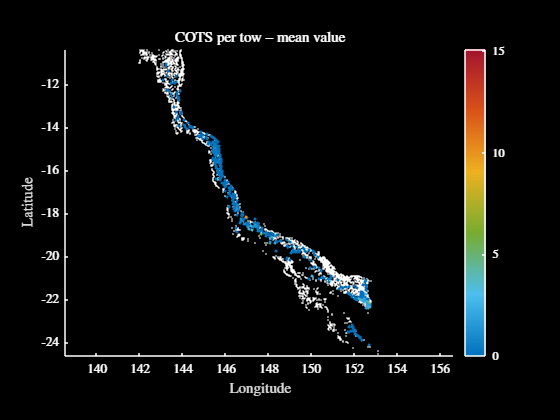

% let's just visualise it real quick
figure
hold on
plotPoints(centroidsLL, 'markerSize', 0.1)
scatter(cotsDensData.x, cotsDensData.y, 6, ...
    cotsDensData.cotsPerTowMean, 'filled')
colormap(myColourMap("dmTurbo"))
axis equal
colorbar()
title("COTS per tow -- mean value")
xlabel("Longitude")
ylabel("Latitude")
darkFig()

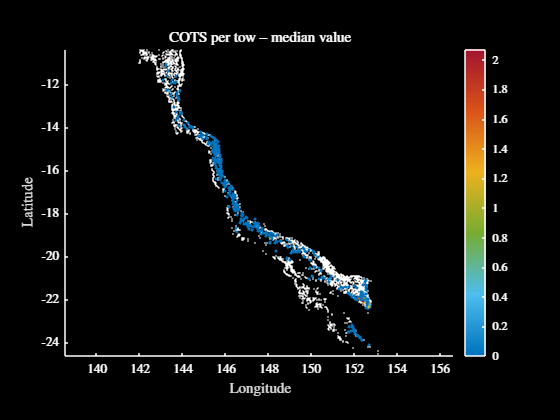

% let's just visualise it real quick
figure
hold on
plotPoints(centroidsLL, 'markerSize', 0.1)
scatter(cotsDensData.x, cotsDensData.y, 6, ...
    cotsDensData.cotsPerTowMedian, 'filled')
colormap(myColourMap("dmTurbo"))
axis equal
colorbar()
title("COTS per tow -- median value")
xlabel("Longitude")
ylabel("Latitude")
darkFig()

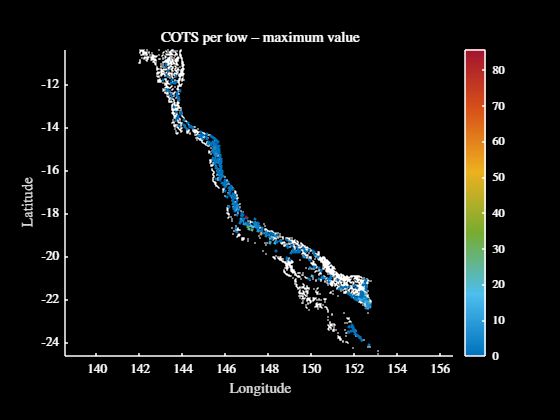

figure
hold on
plotPoints(centroidsLL, 'markerSize', 0.1)
scatter(cotsDensData.x, cotsDensData.y, 6, ...
    cotsDensData.cotsPerTowMax, 'filled')
colormap(myColourMap("dmTurbo"))
axis equal
colorbar()
title("COTS per tow -- maximum value")
xlabel("Longitude")
ylabel("Latitude")
darkFig()

## Larval Supply Figures

% alright, now need to load in the outbreaking data
outbreakDataMatlab = readtable("../Data/Matlab Transfer/" + ...
    "outbreakDataMatlab");
outbreakData = readtable("../Data/Matlab Transfer/outbreakData");

% let's make some masks so that my life is easier
outbrReefs = outbreakDataMatlab.outbreak == 1;
nonOutbrReefs = outbreakDataMatlab.outbreak == 0;
obsReefs = (outbreakDataMatlab.outbreak == 0) ...
    + (outbreakDataMatlab.outbreak == 1) > 0;

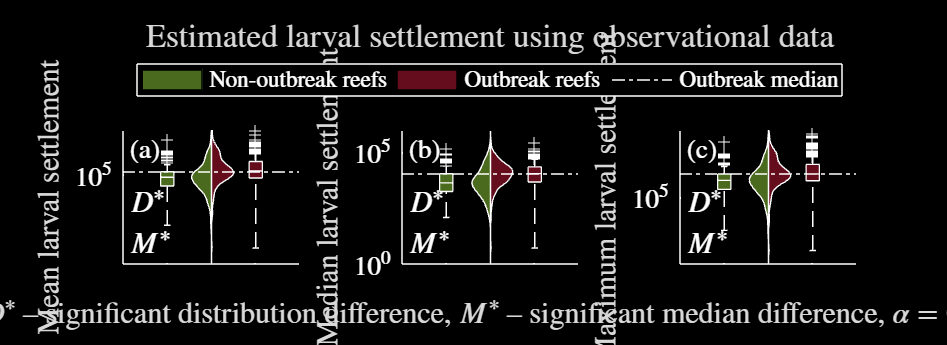

cotsPerTowMeanImput
Mean non-outbreaks: 

ans = 2.0612e+05

Mean outbreaks: 

ans = 4.7475e+05

KS test

p = 1.7941e-05

Median test

p = 4.8913e-06

--------------------------------------------------
cotsPerTowMedianImput
Mean non-outbreaks: 

ans = 1.2246e+04

Mean outbreaks: 

ans = 2.0094e+04

KS test

p = 1.5585e-06

Median test

p = 1.4986e-06

--------------------------------------------------
cotsPerTowMaxImput
Mean non-outbreaks: 

ans = 1.5918e+06

Mean outbreaks: 

ans = 3.5013e+06

KS test

p = 1.3147e-04

Median test

p = 4.4014e-05

--------------------------------------------------


% let's plot the results when we do no imputation, and just use the
% observational data directly
cotsDensNoImput = readtable("../Data/Matlab Transfer/cotsDensNoImput.csv");
var1 = ["", "DM"];
figure
figResize(1.5, 1)

% now do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensNoImput, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using observational " + ...
        "data", i == 2, false)
    saveFig("estimatedLarvSuppNoInterp" + var1(i))
end

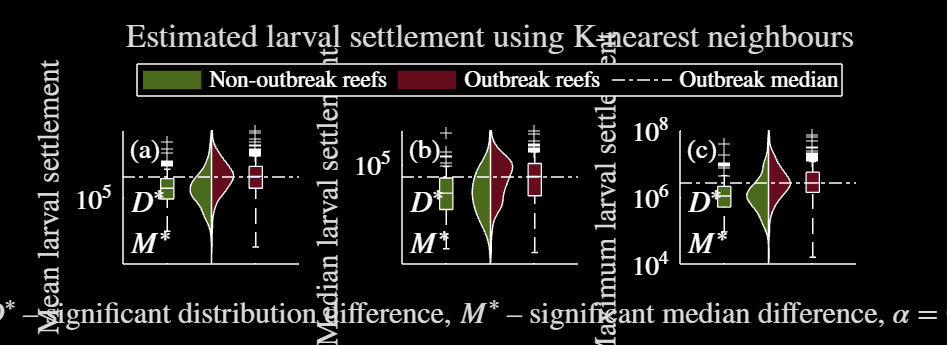

cotsPerTowMeanImput
Mean non-outbreaks: 

ans = 3.7966e+05

Mean outbreaks: 

ans = 8.1466e+05

KS test

p = 6.1880e-08

Median test

p = 1.4986e-06

--------------------------------------------------
cotsPerTowMedianImput
Mean non-outbreaks: 

ans = 4.0150e+04

Mean outbreaks: 

ans = 7.8562e+04

KS test

p = 3.6113e-06

Median test

p = 1.5090e-05

--------------------------------------------------
cotsPerTowMaxImput
Mean non-outbreaks: 

ans = 2.5194e+06

Mean outbreaks: 

ans = 5.3534e+06

KS test

p = 2.0788e-09

Median test

p = 7.4900e-09

--------------------------------------------------


% let's plot the results when use a knn for the imputation
cotsDensKnn = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
figure
figResize(1.5, 1)

% loop over the light and dark mode figures
var1 = ["", "DM"];

% now do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensKnn, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using " + ...
        "K-nearest neighbours", ...
        i == 2, false)
    saveFig("estimatedLarvSuppKnn" + var1(i))
end

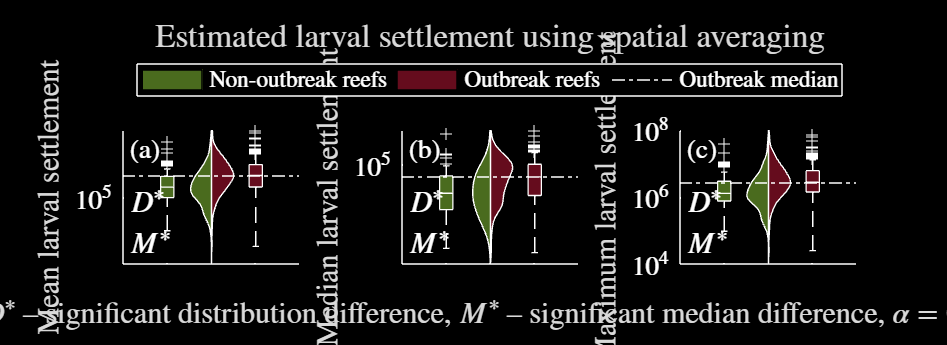

cotsPerTowMeanImput
Mean non-outbreaks: 

ans = 4.0582e+05

Mean outbreaks: 

ans = 8.5365e+05

KS test

p = 2.4386e-07

Median test

p = 4.8913e-06

--------------------------------------------------
cotsPerTowMedianImput
Mean non-outbreaks: 

ans = 4.1951e+04

Mean outbreaks: 

ans = 7.9533e+04

KS test

p = 1.2943e-05

Median test

p = 4.4014e-05

--------------------------------------------------
cotsPerTowMaxImput
Mean non-outbreaks: 

ans = 2.8769e+06

Mean outbreaks: 

ans = 5.6337e+06

KS test

p = 1.4997e-06

Median test

p = 1.4986e-06

--------------------------------------------------


% now let's do the spatial averaging approach
cotsDensSpatAve = readtable("../Data/Matlab Transfer/cotsDensSpatAve.csv");
figure
figResize(1.5, 1)
var1 = ["", "DM"];

% then do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensSpatAve, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using " + ...
        "spatial averaging", ...
        i == 2, false)
    saveFig("estimatedLarvSuppSpatAve" + var1(i))
end

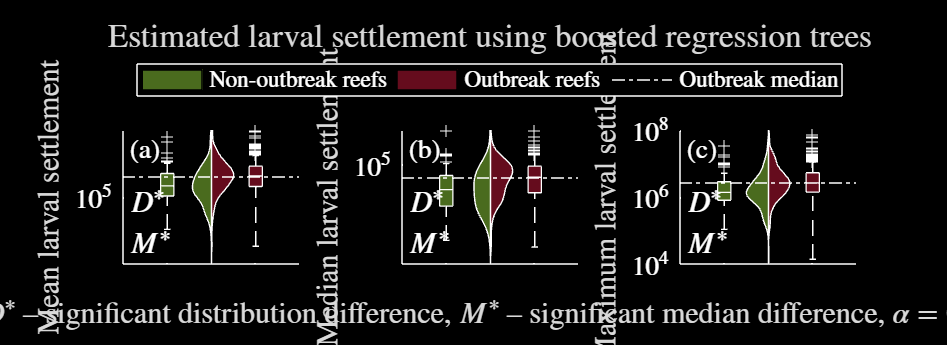

cotsPerTowMeanImput
Mean non-outbreaks: 

ans = 4.6764e+05

Mean outbreaks: 

ans = 7.9842e+05

KS test

p = 5.9424e-05

Median test

p = 1.2139e-04

--------------------------------------------------
cotsPerTowMedianImput
Mean non-outbreaks: 

ans = 4.7194e+04

Mean outbreaks: 

ans = 7.0753e+04

KS test

p = 2.3643e-04

Median test

p = 1.2139e-04

--------------------------------------------------
cotsPerTowMaxImput
Mean non-outbreaks: 

ans = 2.8892e+06

Mean outbreaks: 

ans = 5.1709e+06

KS test

p = 9.3988e-05

Median test

p = 4.4014e-05

--------------------------------------------------


% now let's do the brt approach V2
cotsDensBrt = readtable("../Data/Matlab Transfer/" + ...
    "cotsDensBrtV2.csv");

% then do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using boosted " + ...
        "regression trees", i == 2, false)
    saveFig("estimatedLarvSuppBrtV2" + var1(i))
end

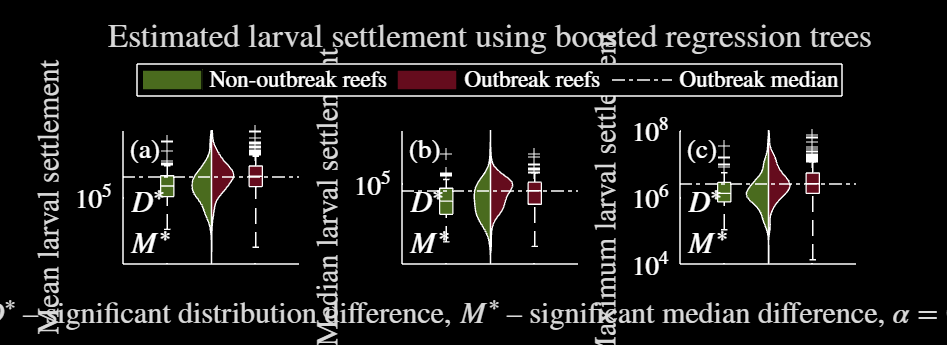

cotsPerTowMeanImput
Mean non-outbreaks: 

ans = 4.3363e+05

Mean outbreaks: 

ans = 7.9930e+05

KS test

p = 1.9545e-05

Median test

p = 4.8913e-06

--------------------------------------------------
cotsPerTowMedianImput
Mean non-outbreaks: 

ans = 6.0558e+04

Mean outbreaks: 

ans = 8.9112e+04

KS test

p = 0.0011

Median test

p = 7.8158e-04

--------------------------------------------------
cotsPerTowMaxImput
Mean non-outbreaks: 

ans = 2.7146e+06

Mean outbreaks: 

ans = 5.0447e+06

KS test

p = 1.6621e-05

Median test

p = 4.4014e-05

--------------------------------------------------


% now let's do the brt approach V3
cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");

% then do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement using boosted " + ...
        "regression trees", i == 2, false)
    saveFig("estimatedLarvSuppBrtV3" + var1(i))
end

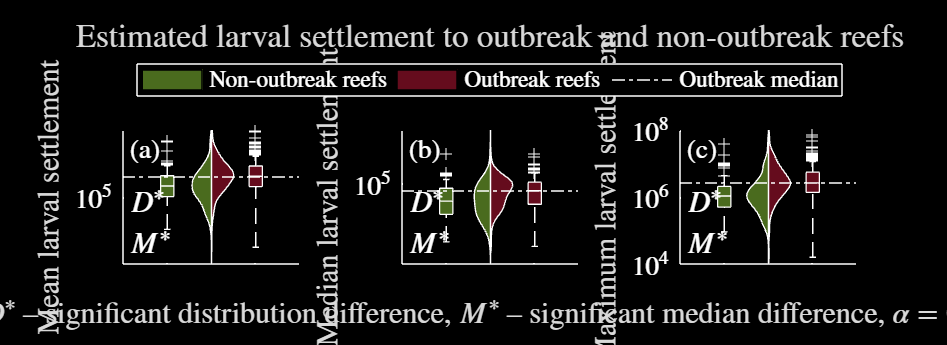

cotsPerTowMeanImput
Mean non-outbreaks: 

ans = 4.3363e+05

Mean outbreaks: 

ans = 7.9930e+05

KS test

p = 1.9545e-05

Median test

p = 4.8913e-06

--------------------------------------------------
cotsPerTowMedianImput
Mean non-outbreaks: 

ans = 6.0558e+04

Mean outbreaks: 

ans = 8.9112e+04

KS test

p = 0.0011

Median test

p = 7.8158e-04

--------------------------------------------------
cotsPerTowMaxImput
Mean non-outbreaks: 

ans = 2.5194e+06

Mean outbreaks: 

ans = 5.3534e+06

KS test

p = 2.0788e-09

Median test

p = 7.4900e-09

--------------------------------------------------


% alright let's do the final one, where I'm using the brt for both mean and
% median, and then the knn for the maximum
cotsDensBrt = readtable("../Data/Matlab Transfer/cotsDensBrtV3.csv");
var1 = readtable("../Data/Matlab Transfer/cotsDensKnn.csv");
cotsDensBrt.cotsPerTowMaxImput = var1.cotsPerTowMaxImput;
var1 = ["", "DM"];

% then do the boxplots
figure
figResize(1, 1.75)
for i = 1:2
    clf()
    plotLarvalSupplyV2(cotsDensBrt, conMatGlobal, nonOutbrReefs, ...
        outbrReefs, "Estimated larval settlement to outbreak and " + ...
        "non-outbreak reefs", i == 2, false)
    saveFig("estimatedLarvSupp" + var1(i))
end

## Spatial Averages Visualisation

% I wanna actually have a look at the observations we have, and eyeball
% whether or not there is much spatial autocorrelation
cotsDensData = readtable("../Data/Matlab Transfer/cotsDensData.csv");

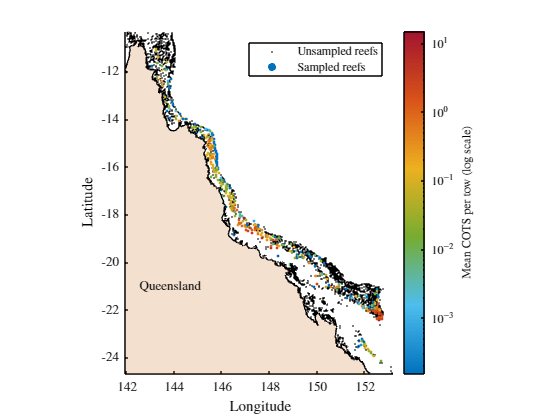

% plot stufv :3
figure
hold on
plotPoints(centroidsLL)
scatter(cotsDensData.x, cotsDensData.y, 4, ...
    cotsDensData.cotsPerTowMean, 'filled')
colormap(myColourMap("dmTurbo"))
set(gca, 'colorscale', 'log')
cBar = colorbar();
ylabel(cBar, "Mean COTS per tow (log scale)", "Interpreter", "latex")
latLonLabs
plotQldOutline(qldOutline)
legend("Unsampled reefs", "Sampled reefs", 'location', 'northeast')
axis equal
axis(gbrBoundaryLL)
darkFig()
saveFig("cotsPerTowObsMeanDM")
lightFig()
saveFig("cotsPerTowObsMean")

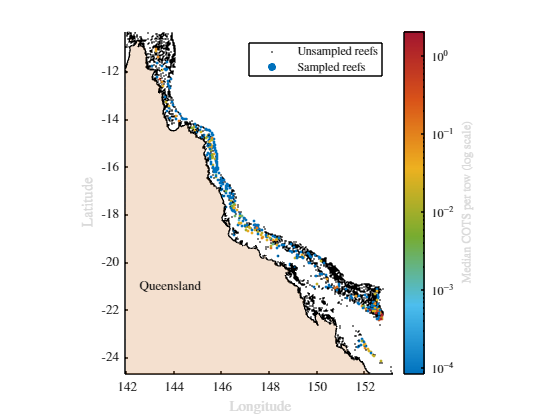

figure
hold on
plotPoints(centroidsLL)
scatter(cotsDensData.x, cotsDensData.y, 4, ...
    cotsDensData.cotsPerTowMedian, 'filled')
colormap(myColourMap("dmTurbo"))
set(gca, 'colorscale', 'log')
cBar = colorbar();
ylabel(cBar, "Median COTS per tow (log scale)", "Interpreter", "latex")
latLonLabs
plotQldOutline(qldOutline)
legend("Unsampled reefs", "Sampled reefs", 'location', 'northeast')
axis equal
axis(gbrBoundaryLL)
darkFig()
saveFig("cotsPerTowObsMedianDM")
lightFig()
saveFig("cotsPerTowObsMedian")

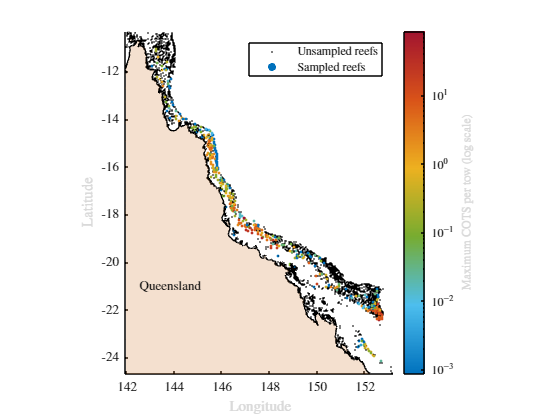

figure
hold on
plotPoints(centroidsLL)
scatter(cotsDensData.x, cotsDensData.y, 4, ...
    cotsDensData.cotsPerTowMax, 'filled')
colormap(myColourMap("dmTurbo"))
set(gca, 'colorscale', 'log')
cBar = colorbar();
ylabel(cBar, "Maximum COTS per tow (log scale)", "Interpreter", "latex")
latLonLabs
plotQldOutline(qldOutline)
legend("Unsampled reefs", "Sampled reefs", 'location', 'northeast')
axis equal
axis(gbrBoundaryLL)
darkFig()
saveFig("cotsPerTowObsMaxDM")
lightFig()
saveFig("cotsPerTowObsMax")

% let's look at our predictions of the mean, median, and maximum cots
% densities next to their true values so that I can try get a vague idea of
% whether the predictions look reasonable